## 0: Loading in Data and preliminary calculations from previous labs

Note that you can modify all of the code to be for the high vs low pt data set by changing data_index. But for the remainder of the lab, all numbers cited and optimized for will be with the low pt data set (data_index = 1).

feature_labels = {'pt', 'eta', 'phi', 'mass', 'ee2', 'ee3', 'd2', 'angularity', ...
    't1', 't2', 't3', 't21', 't32', 'KtDeltaR'};

data_index = 1;

qcd_data_labels = ["qcd_100000_pt_250_500", "qcd_100000_pt_1000_1200"];
higgs_data_labels = ["higgs_100000_pt_250_500", "higgs_100000_pt_1000_1200"];

qcd_label = qcd_data_labels(data_index);
higgs_label = higgs_data_labels(data_index);

h5disp("data/" + qcd_label +".h5")

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



h5disp("data/" + higgs_label +".h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



qcd_data = h5read("data/" + qcd_label+".h5", ['/' convertStringsToChars(qcd_label)]);
higgs_data = h5read("data/" + higgs_label +".h5",['/' convertStringsToChars(higgs_label)]);

% puts in form so first index is for each data point, second is for each
% quantity measured
qcd_data = qcd_data';
higgs_data = higgs_data';


## 1: Mass Comparison of Higgs vs QCD Background and Initial Significance

Below is a calculation taken from lab 5 in which we calculated the significance of detecting the Higgs with no cuts.


n_higgs_list = [100, 50];
n_qcd_list = [20000, 2000];

n_higgs = n_higgs_list(data_index);
n_qcd = n_qcd_list(data_index);

background_prob_to_observe_total = 1- poisscdf(n_qcd + n_higgs, n_qcd)

background_prob_to_observe_total = 0.2385


no_cut_significance = norminv(1-background_prob_to_observe_total)

no_cut_significance = 0.7112

snr = n_higgs / sqrt(n_qcd)

snr = 0.7071

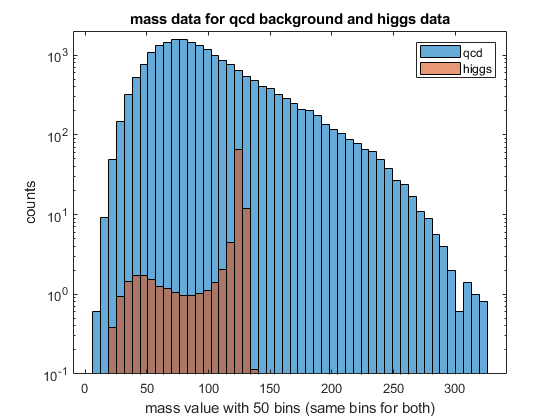


qcd_mass_data = qcd_data(:, 4);
higgs_mass_data = higgs_data(:, 4);

qcd_normalization_ratio = n_qcd/length(qcd_mass_data);
higgs_normalization_ratio = n_higgs/length(higgs_mass_data);

label = feature_labels{4};
nbins = 50;

[~, full_hist_bins] = histcounts([qcd_mass_data, higgs_mass_data], nbins);

mass_full_hist_bins = full_hist_bins;

figure
qcd_mass_hist_counts = histcounts(qcd_mass_data, full_hist_bins);
normalized_qcd_mass_hist_counts = (qcd_normalization_ratio*qcd_mass_hist_counts);

higgs_mass_hist_counts = histcounts(higgs_mass_data, full_hist_bins);
normalized_higgs_mass_hist_counts = ...
    (higgs_normalization_ratio*higgs_mass_hist_counts);

histogram('BinCounts',normalized_qcd_mass_hist_counts, 'BinEdges',full_hist_bins)
hold on
histogram('BinCounts',normalized_higgs_mass_hist_counts, 'BinEdges',full_hist_bins)

title([label ' data for qcd background and higgs data'])
xlabel([label ' value with ' num2str(nbins) ' bins (same bins for both)'])
ylabel('counts')
ylim([0.1, 2*10^3])
set(gca, 'Yscale', 'log')
legend({'qcd', 'higgs'})

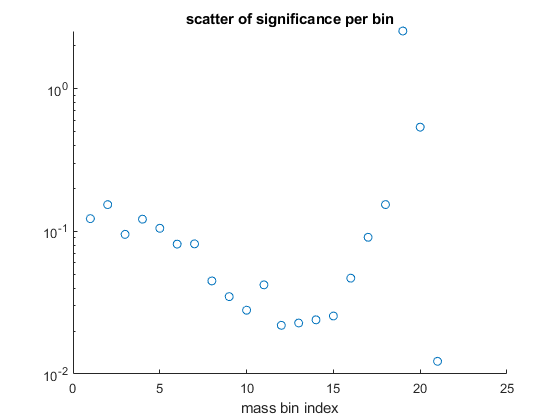

mass_bins_to_use_list = find(normalized_higgs_mass_hist_counts ~= 0);

mass_per_bin_significance = norminv(poisscdf(normalized_higgs_mass_hist_counts + normalized_qcd_mass_hist_counts, normalized_qcd_mass_hist_counts));

figure

scatter(mass_bins_to_use_list, mass_per_bin_significance(mass_bins_to_use_list))
title('scatter of significance per bin')
xlabel('mass bin index')
set(gca, 'Yscale', 'log')
datacursormode on

## 2. Identifying mass cuts to optimize expected significance

We will look at subsets of the bins from the histogram above to calculate the optimal mass cuts. I will again be using the restrict data function that I created in lab 5, included at the end of this lab. I start by using the maximum value of the higgs mass data to immediately throw out a large portion of the background data. Then, because of the relative few bins that actually have higgs events, it is possible to brute force over all combinations of those to find their significances. 


no_higgs_bins = find(normalized_higgs_mass_hist_counts == 0);


mass_bins_to_use_list = find(normalized_higgs_mass_hist_counts ~= 0);

bin_inclusion_number = 2^(length(mass_bins_to_use_list)-1);

bin_inclusion_binary_list = logical(de2bi(1:bin_inclusion_number));

significance_list = zeros(1, bin_inclusion_number);

nhiggs_per_cut_list = zeros(1, bin_inclusion_number);
nbackground_per_cut_list = zeros(1, bin_inclusion_number);

for i = 1:bin_inclusion_number
    bin_inclusion_binary = bin_inclusion_binary_list(i, :);
    mass_bins_to_use = mass_bins_to_use_list(bin_inclusion_binary);
    nhiggs = sum(normalized_higgs_mass_hist_counts(mass_bins_to_use));
    nbackground = sum(normalized_qcd_mass_hist_counts(mass_bins_to_use));
    
    nbackground_per_cut_list(i) = nbackground;
    nhiggs_per_cut_list(i) = nhiggs;
    significance_list(i) = norminv(poisscdf(nbackground+nhiggs, nbackground));
    mass_significance(i).bins = mass_bins_to_use;
end

Looking at a histogram of the significances for different mass cuts, we see that the best we can do with just a mass cut is around a significance estimate of around 2.5.

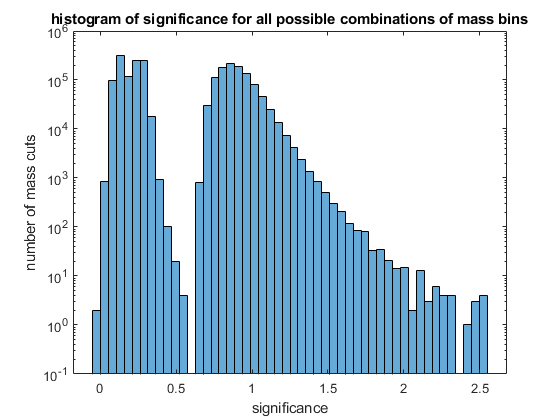

nbins = 50;
figure
[hist_vals, hist_bin_edges] = histcounts(significance_list,nbins);
histogram('BinCounts', hist_vals, 'BinEdges',hist_bin_edges)
title('histogram of significance for all possible combinations of mass bins')
xlabel('significance')
ylabel('number of mass cuts')
ylim([0.1, 10^6])
set(gca, 'YScale', 'log')
datacursormode on

Below I plot significance vs number of higgs events kept. While it might seem that the best place to start is the cut with the most significance, if we are doing a second cut later and there is any correlation between the two parameters, it might be important to start with a less restrictive cut. That being said, for similar significance values, it seems intuitive to use the cut that include the most higgs events. Furthermore, the plot is interesting. We see two similarly shaped higgs events vs significance sections that are distinct. This can arise due to a particular bin in the mass cuts that has a lot of higgs events

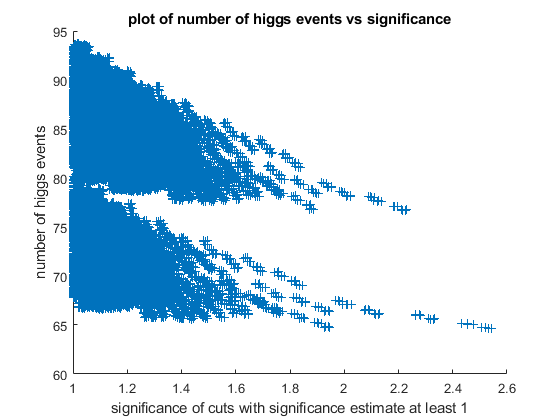

significance_threshold = 1;

more_significant_cuts = find(significance_list > significance_threshold);

restricted_significances = significance_list(more_significant_cuts);
restricted_nhiggs = nhiggs_per_cut_list(more_significant_cuts);
restricted_nbackground = nbackground_per_cut_list(more_significant_cuts);

figure
scatter(restricted_significances, restricted_nhiggs, '+')
title('plot of number of higgs events vs significance')
xlabel(['significance of cuts with significance estimate at least ' num2str(significance_threshold)])
ylabel('number of higgs events')
datacursormode on

From the above plot of higgs events vs significance and the earlier significance per bin scatter plot.

per_bin_significance_threshold = 0.15;

significant_mass_bins = mass_per_bin_significance > per_bin_significance_threshold;
has_higgs_signal = normalized_higgs_mass_hist_counts > 0;

mass_cut_bins = find(significant_mass_bins.*has_higgs_signal)

mass_cut_bins =      2    18    19    20



mass_cut_nhiggs = sum(normalized_higgs_mass_hist_counts(mass_cut_bins))

mass_cut_nhiggs = 81.1490

mass_cut_nbackground = sum(normalized_qcd_mass_hist_counts(mass_cut_bins))

mass_cut_nbackground = 1.9448e+03

mass_cut_significance = norminv(poisscdf(mass_cut_nbackground+mass_cut_nhiggs, mass_cut_nbackground))

mass_cut_significance = 1.8212

## 3. Making stacked histogram plots for other features

Without any mass cuts, we below overplot the qcd and higgs data:

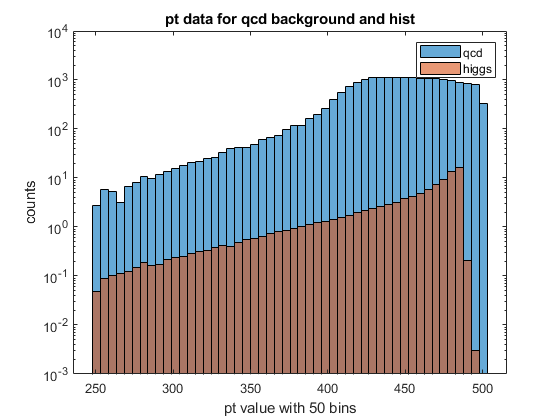

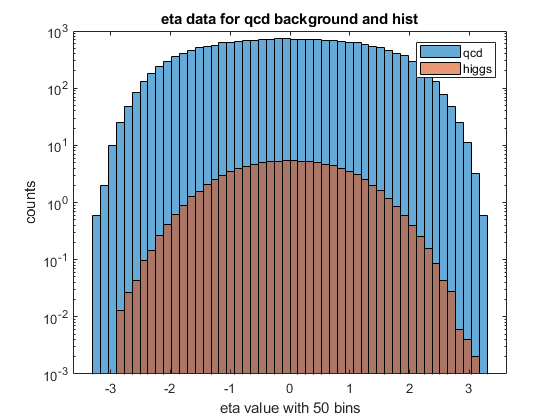

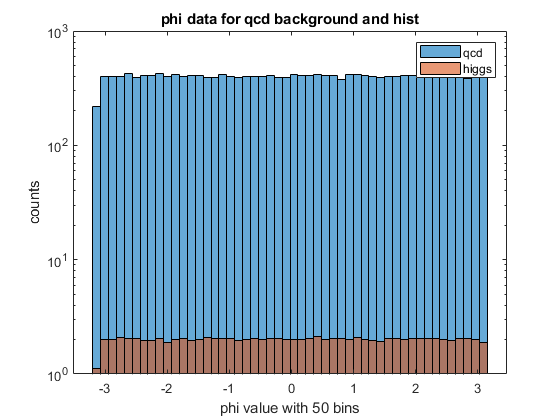

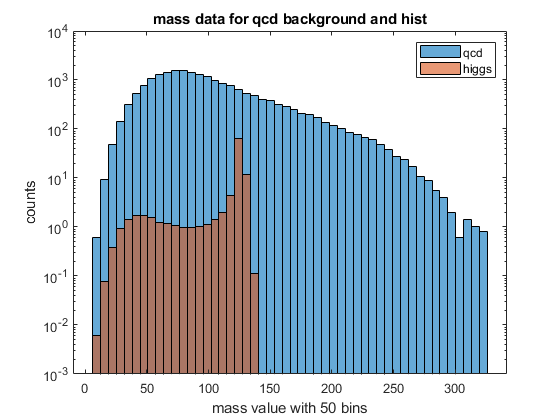

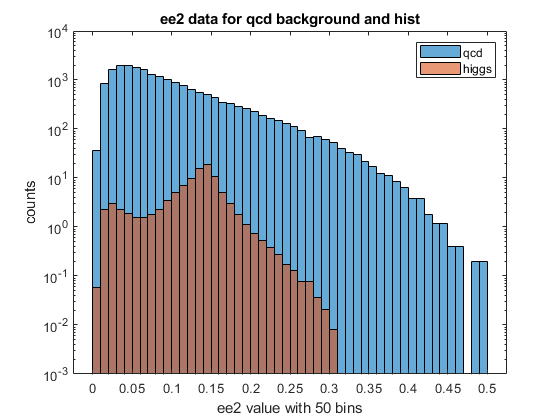

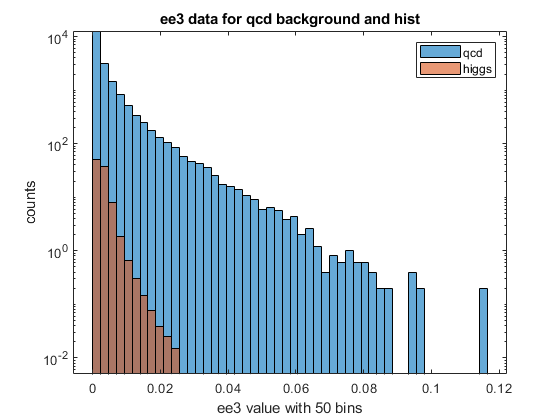

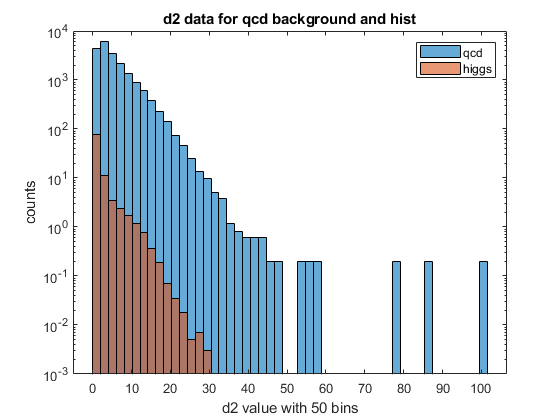

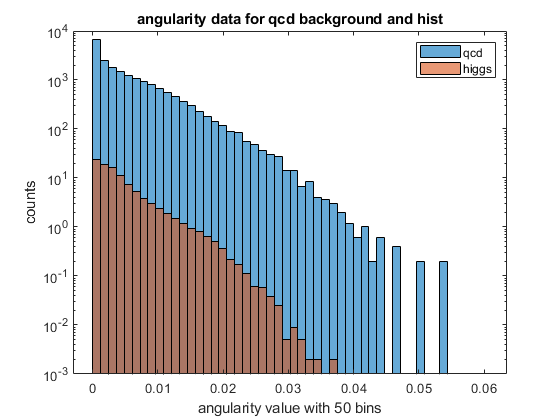

for i=1:length(feature_labels)
    
    label = feature_labels{i};
    nbins = 50;
    
    feature_qcd_data = qcd_data(:, i);
    feature_higgs_data = higgs_data(:, i);
    
    [~, full_hist_bins] = histcounts([feature_qcd_data, feature_higgs_data], nbins);
    figure
    
    qcd_hist_counts = histcounts(feature_qcd_data, full_hist_bins);
    normalized_qcd_hist_counts = (qcd_normalization_ratio*qcd_hist_counts);
    
    higgs_hist_counts = histcounts(feature_higgs_data, full_hist_bins);
    normalized_higgs_hist_counts = ...
        (higgs_normalization_ratio*higgs_hist_counts);
    
    histogram('BinCounts',normalized_qcd_hist_counts, 'BinEdges',full_hist_bins)
    hold on
    histogram('BinCounts',normalized_higgs_hist_counts, 'BinEdges',full_hist_bins)
    

    title([label ' data for qcd background and hist'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    legend({'qcd', 'higgs'})

    
end

Now we first restrict the data using a mass cut from earlier, and again look at the overplot of the higgs data and the qcd data. 

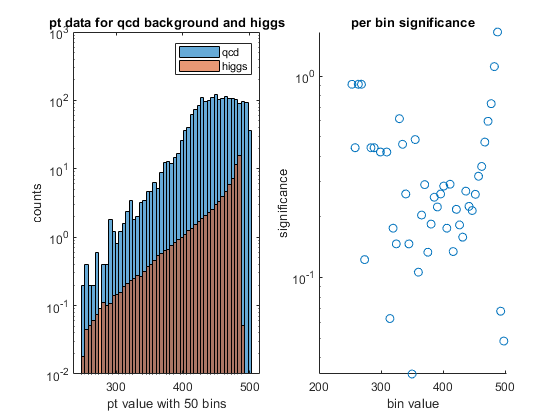

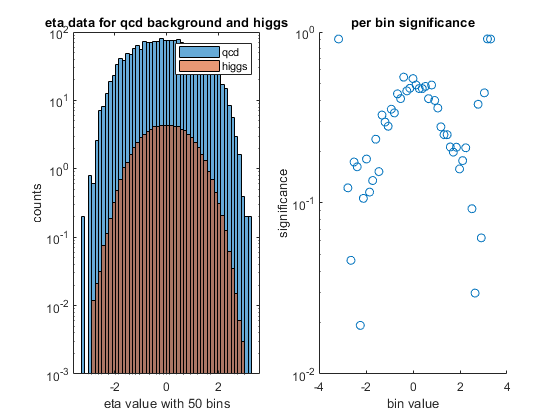

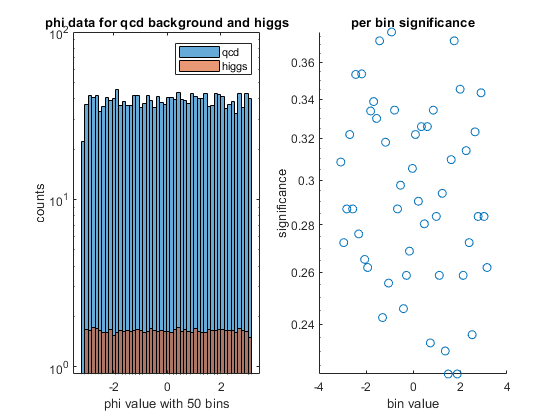

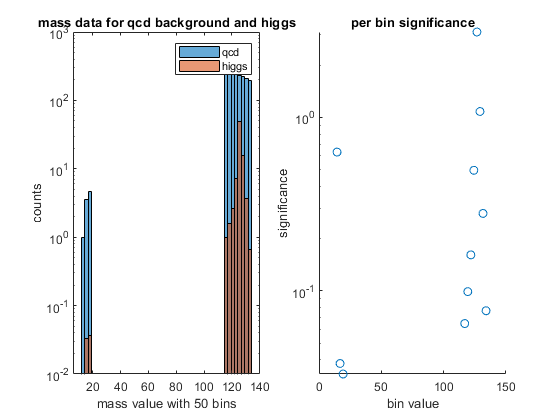

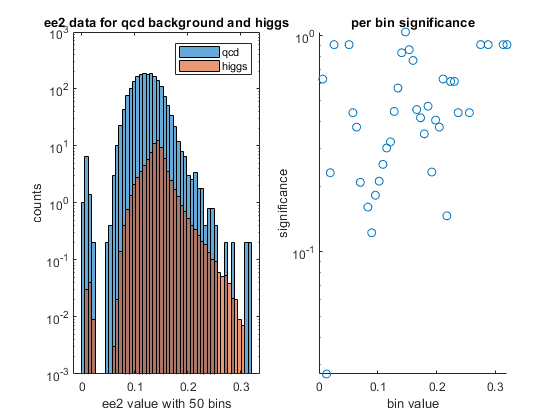

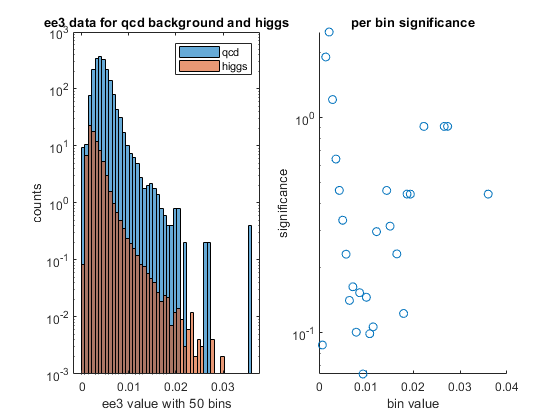

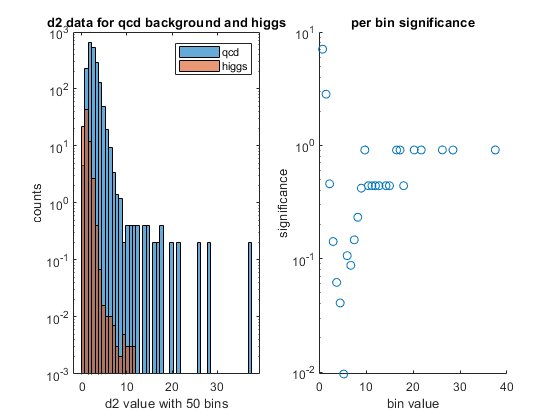

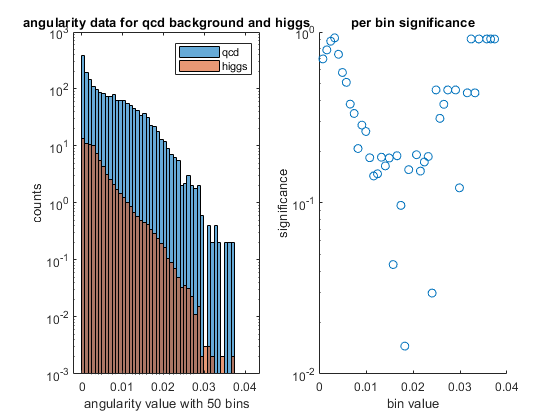

% mass_cut_bins : 1D array with bin indices from mass_full_hist_bins
% included in mass cut

% mass_full_hist_bins : 1D array with edges of mass hist bins

mass_included_ranges = zeros(2, length(mass_cut_bins));

for j = 1:length(mass_cut_bins)
    mass_included_ranges(1, j) = mass_full_hist_bins(mass_cut_bins(j));
    mass_included_ranges(2, j) = mass_full_hist_bins(mass_cut_bins(j)+1);
end

mass_index = 4;

qcd_data_restricted = restrict_data(qcd_data, mass_index, mass_included_ranges);
higgs_data_restricted = restrict_data(higgs_data, mass_index, mass_included_ranges);

for i=1:length(feature_labels)
    
    label = feature_labels{i};
    nbins = 50;
    
    feature_qcd_data = qcd_data_restricted(:, i);
    feature_higgs_data = higgs_data_restricted(:, i);
    
    [~, full_hist_bins] = histcounts([feature_qcd_data', feature_higgs_data'], nbins);
    
    figure
    subplot(1,2,1)
    qcd_hist_counts = histcounts(feature_qcd_data, full_hist_bins);
    normalized_qcd_hist_counts = (qcd_normalization_ratio*qcd_hist_counts);
    
    higgs_hist_counts = histcounts(feature_higgs_data, full_hist_bins);
    normalized_higgs_hist_counts = ...
        (higgs_normalization_ratio*higgs_hist_counts);
    
    qcd_hist_post_mass_cut(i) = histogram('BinCounts',normalized_qcd_hist_counts, 'BinEdges',full_hist_bins);
    hold on
    higgs_hist_post_mass_cut(i) = histogram('BinCounts',normalized_higgs_hist_counts, 'BinEdges',full_hist_bins);


    title([label ' data for qcd background and higgs'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    legend({'qcd', 'higgs'})
    
    subplot(1,2,2)
    
    per_bin_significance(i, :) = norminv(poisscdf(normalized_qcd_hist_counts+normalized_higgs_hist_counts, normalized_qcd_hist_counts));
    per_bin_significance(i, :) = max(0, per_bin_significance(i, :));
    scatter(full_hist_bins(1:end-1) + full_hist_bins(2)-full_hist_bins(1), per_bin_significance(i,:))
    set(gca, 'Yscale', 'log')
    title('per bin significance')
    xlabel('bin value')
    ylabel('significance')
    
     
    
end

## 4. Optimizing Event Selections Using Multiple Features

When selecting other quantities to use for cutting, it can be appealing to jump to plots where there are regions that have Higgs signal and no background. But, recalling that these are normalized to the expected number of Higgs/QCD background events seen over the whole data set, we see that ususually the expected number of Higgs events in these regions is still less than 1, often significantly so. As a consequence, even if those regions have no expected QCD background events, you would not actually expect to see the Higgs signal either! Essentially, it is in these regions, with little to no background that the approximation of N_Higgs/sqrt(N_QCD) breaks down, and instead you have to actually calculate the significance. 



restricted_qcd = qcd_data_restricted;
restricted_higgs = higgs_data_restricted;

feature_labels = {'pt', 'eta', 'phi', 'mass', 'ee2', 'ee3', 'd2', 'angularity', ...
    't1', 't2', 't3', 't21', 't32', 'KtDeltaR'};

% started by doing cut-offs for all indices, then went back and only used
% the ones that were most discriminatory (mass, d2, t3)

% comparison_indices = 1:14;
% per_bin_significance_cutoffs = 0.15*ones(size(comparison_indices));
% per_bin_significance_cutoffs(11) = 1;

comparison_indices = [4,7,11];
per_bin_significance_cutoffs = [0.15, 1, 1];

for i=1:length(comparison_indices)
    index = comparison_indices(i);
    boundary = per_bin_significance_cutoffs(i);
    significant_bins = per_bin_significance(index, :) >= boundary;
    has_higgs_signal = higgs_hist_post_mass_cut(index).Values > 0;
    
    included_bins = find(significant_bins.*has_higgs_signal);
    
    included_ranges = zeros(2, length(included_bins));
    
    for j = 1:length(included_bins)
        included_ranges(1, j) = higgs_hist_post_mass_cut(index).BinEdges(included_bins(j));
        included_ranges(2, j) = higgs_hist_post_mass_cut(index).BinEdges(included_bins(j)+1);
    end
    
    restricted_qcd = restrict_data(restricted_qcd, index, included_ranges);
    restricted_higgs = restrict_data(restricted_higgs, index, included_ranges);
    
    cuts_for_index{index} = included_ranges;
end

qcd_data_size = size(qcd_data);
higgs_data_size = size(higgs_data);

restricted_qcd_size = size(restricted_qcd);
restricted_higgs_size = size(restricted_higgs);

fraction_qcd_kept = restricted_qcd_size(1)/qcd_data_size(1)

fraction_qcd_kept = 0.0023

fraction_higgs_kept = restricted_higgs_size(1)/higgs_data_size(1)

fraction_higgs_kept = 0.4735

nqcd = n_qcd*fraction_qcd_kept;
nhiggs = n_higgs*fraction_higgs_kept;

discovery_sensitivity = 1 - poisscdf(nqcd+nhiggs, nqcd)

discovery_sensitivity = 4.0616e-10

sensitivity_sigma = norminv(1 - discovery_sensitivity)

sensitivity_sigma = 6.1425

## 6. Pseudo-experiments - loading the data in

high_lumin_data_labels = ["data_highLumi_pt_250_500", "data_highLumi_pt_1000_1200"];
low_lumin_labels = ["data_lowLumi_pt_250_500", "data_lowLumi_pt_1000_1200"];

high_lumin_label = high_lumin_data_labels(data_index);
low_lumin_label = low_lumin_labels(data_index);

% commented out to save space now, but originally used to figure out data
% to load
% h5disp("data/" + high_lumin_label +".h5")

% h5disp("data/" + low_lumin_label +".h5")

high_lumin_data = h5read("data/" + high_lumin_label +".h5", '/data/block0_values');
low_lumin_data = h5read("data/" + low_lumin_label +".h5", '/data/block0_values');

% puts in form so first index is for each data point, second is for each
% quantity measured
high_lumin_data = high_lumin_data';
low_lumin_data = low_lumin_data';

## 7. High Luminosity Data


restricted_high_lumin_data = high_lumin_data;

for i = comparison_indices
    included_ranges = cuts_for_index{i};
    
    restricted_high_lumin_data = restrict_data(restricted_high_lumin_data, i, included_ranges);
    
end

restricted_qcd_data = qcd_data;

for i = comparison_indices
    included_ranges = cuts_for_index{i};
    
    restricted_qcd_data = restrict_data(restricted_qcd_data, i, included_ranges);
    
end

restricted_higgs_data = higgs_data;

for i = comparison_indices
    included_ranges = cuts_for_index{i};
    
    restricted_higgs_data = restrict_data(restricted_higgs_data, i, included_ranges);
    
end

Below we plot the data over the expected signal and the expected background both with and without the cuts:

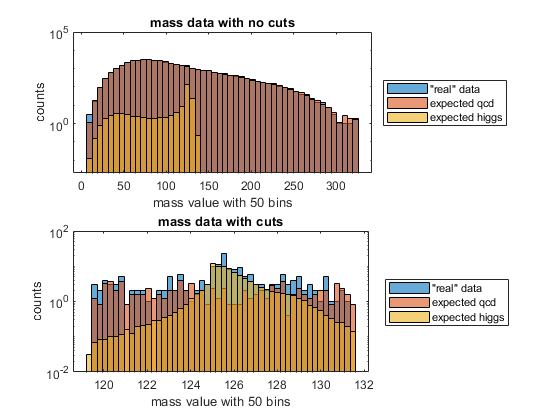

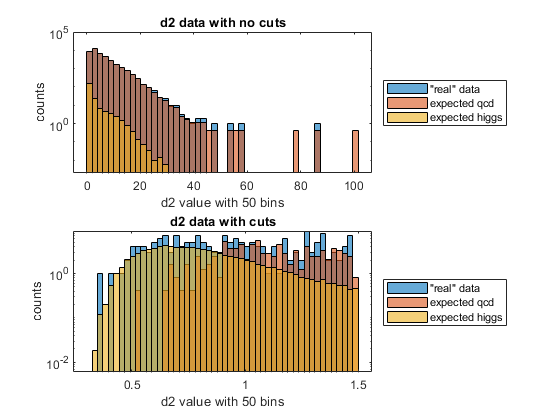

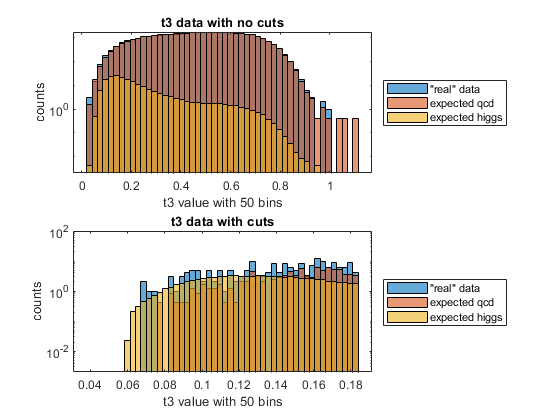

total_events_high_lumin = length(high_lumin_data);
fraction_signal_higgs = n_higgs_list(data_index)/(n_higgs_list(data_index) + n_qcd_list(data_index));
fraction_signal_qcd = n_qcd_list(data_index)/(n_higgs_list(data_index) + n_qcd_list(data_index));

expected_qcd = total_events_high_lumin*fraction_signal_qcd;
expected_higgs = total_events_high_lumin*fraction_signal_higgs;

restricted_expected_qcd = total_events_high_lumin*fraction_signal_qcd;
restrcited_expected_higgs = total_events_high_lumin*fraction_signal_higgs;

fraction_qcd_kept = length(restricted_qcd_data) / length(qcd_data);
total_qcd_expected_post_cut = expected_qcd*fraction_qcd_kept;
fraction_higgs_kept = length(restricted_higgs_data) / length(higgs_data);
total_higgs_expected_post_cut = expected_higgs*fraction_higgs_kept;
total_expected_post_cut = total_higgs_expected_post_cut + total_qcd_expected_post_cut;
actual_amount_kept = length(restricted_high_lumin_data);

for i = comparison_indices
    
    label = feature_labels{i};
    nbins = 50;
    
    feature_qcd_data = qcd_data(:, i);
    feature_higgs_data = higgs_data(:, i);
    
    restricted_feature_qcd_data = restricted_qcd_data(:, i);
    restricted_feature_higgs_data = restricted_higgs_data(:, i);
    
    real_data = high_lumin_data(:, i);
    restricted_feature_real_data = restricted_high_lumin_data(:, i);
    
    [~, full_hist_bins] = histcounts([feature_qcd_data', feature_higgs_data',real_data'], nbins);
    
    qcd_hist_counts = histcounts(feature_qcd_data, full_hist_bins);
    normalized_qcd_hist_counts = (expected_qcd*qcd_hist_counts)/length(qcd_data);
    
    higgs_hist_counts = histcounts(feature_higgs_data, full_hist_bins);
    normalized_higgs_hist_counts = ...
        (expected_higgs*higgs_hist_counts)/length(higgs_data);
    
    real_hist_counts = histcounts(real_data, full_hist_bins);
    
    figure
    clf
    
    subplot(2,1,1)
    
    histogram('BinCounts',real_hist_counts, 'BinEdges',full_hist_bins)
    hold on
    histogram('BinCounts',normalized_qcd_hist_counts, 'BinEdges',full_hist_bins)
    hold on
    histogram('BinCounts',normalized_higgs_hist_counts, 'BinEdges',full_hist_bins)
    
    

    title([label ' data with no cuts'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    legend({'"real" data','expected qcd', 'expected higgs'}, "Location", 'eastoutside')
    
    
    subplot(2,1,2)
    
    [~, full_hist_bins] = histcounts([restricted_feature_qcd_data', restricted_feature_higgs_data',restricted_feature_real_data'], nbins);
    
    qcd_hist_counts = histcounts(restricted_feature_qcd_data, full_hist_bins);
    normalized_qcd_hist_counts = (total_qcd_expected_post_cut*qcd_hist_counts)/length(restricted_qcd_data);
    
    higgs_hist_counts = histcounts(restricted_feature_higgs_data, full_hist_bins);
    normalized_higgs_hist_counts = ...
        (total_higgs_expected_post_cut*higgs_hist_counts)/length(restricted_higgs_data);
    
    real_hist_counts = histcounts(restricted_feature_real_data, full_hist_bins);
    
    histogram('BinCounts',real_hist_counts, 'BinEdges',full_hist_bins)
    hold on
    histogram('BinCounts',normalized_qcd_hist_counts, 'BinEdges',full_hist_bins)
    hold on
    histogram('BinCounts',normalized_higgs_hist_counts, 'BinEdges',full_hist_bins)


    title([label ' data with cuts'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    legend({'"real" data','expected qcd', 'expected higgs'},"Location",'eastoutside')

    

end

We will calculate below the amount of expected qcd background and amount of higgs post cut, and from those and the true amount left post-cut, calculate the significance of Higgs detection. Note that we are scaling the total number events by .995 (for low pt dataset) to approximate what the background signal is for the total data run. We see that matlab's precision is insufficient to calculate the exact significance, so we make an approximation:

significance = norminv(poisscdf(actual_amount_kept, total_qcd_expected_post_cut))

significance = Inf

estimated_significance = (actual_amount_kept - total_qcd_expected_post_cut)/sqrt(total_qcd_expected_post_cut)

estimated_significance = 9.9387

## 8. Low Luminosity Data

restricted_low_lumin_data = low_lumin_data;

for i = comparison_indices
    included_ranges = cuts_for_index{i};
    
    restricted_low_lumin_data = restrict_data(restricted_low_lumin_data, i, included_ranges);
    
end


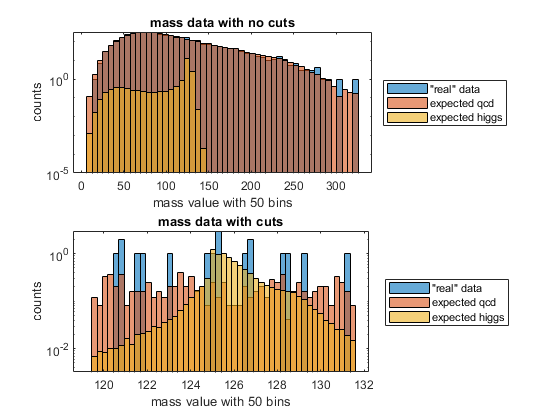

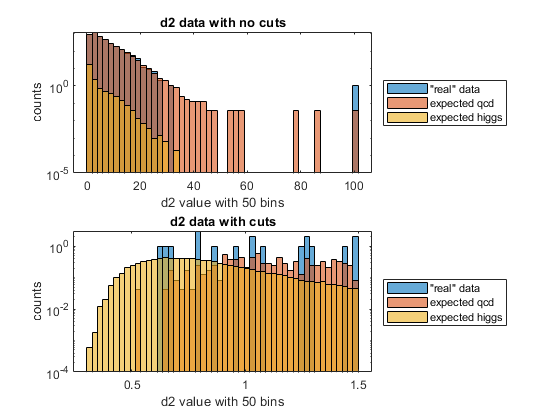

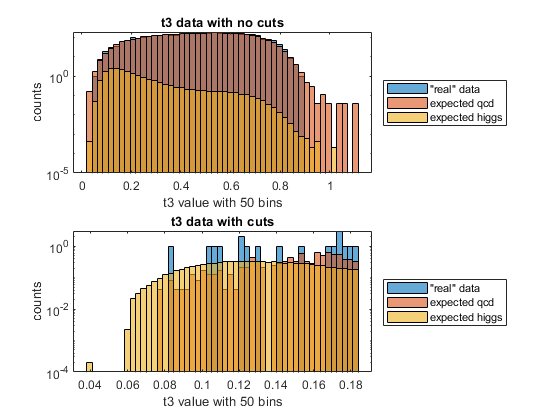

total_events_low_lumin = length(low_lumin_data);
fraction_signal_higgs = n_higgs_list(data_index)/(n_higgs_list(data_index) + n_qcd_list(data_index));
fraction_signal_qcd = n_qcd_list(data_index)/(n_higgs_list(data_index) + n_qcd_list(data_index));

expected_qcd = total_events_low_lumin*fraction_signal_qcd;
expected_higgs = total_events_low_lumin*fraction_signal_higgs;

restricted_expected_qcd = total_events_low_lumin*fraction_signal_qcd;
restrcited_expected_higgs = total_events_low_lumin*fraction_signal_higgs;

fraction_qcd_kept = length(restricted_qcd_data) / length(qcd_data);
total_qcd_expected_post_cut = expected_qcd*fraction_qcd_kept;
fraction_higgs_kept = length(restricted_higgs_data) / length(higgs_data);
total_higgs_expected_post_cut = expected_higgs*fraction_higgs_kept;
total_expected_post_cut = total_higgs_expected_post_cut + total_qcd_expected_post_cut;
actual_amount_kept = length(restricted_low_lumin_data);

for i = comparison_indices
    
    label = feature_labels{i};
    nbins = 50;
    
    feature_qcd_data = qcd_data(:, i);
    feature_higgs_data = higgs_data(:, i);
    
    restricted_feature_qcd_data = restricted_qcd_data(:, i);
    restricted_feature_higgs_data = restricted_higgs_data(:, i);
    
    real_data = low_lumin_data(:, i);
    restricted_feature_real_data = restricted_low_lumin_data(:, i);
    
    [~, full_hist_bins] = histcounts([feature_qcd_data', feature_higgs_data',real_data'], nbins);
    
    qcd_hist_counts = histcounts(feature_qcd_data, full_hist_bins);
    normalized_qcd_hist_counts = (expected_qcd*qcd_hist_counts)/length(qcd_data);
    
    higgs_hist_counts = histcounts(feature_higgs_data, full_hist_bins);
    normalized_higgs_hist_counts = ...
        (expected_higgs*higgs_hist_counts)/length(higgs_data);
    
    real_hist_counts = histcounts(real_data, full_hist_bins);
    
    figure
    
    subplot(2,1,1)
    
    histogram('BinCounts',real_hist_counts, 'BinEdges',full_hist_bins)
    hold on
    histogram('BinCounts',normalized_qcd_hist_counts, 'BinEdges',full_hist_bins)
    hold on
    histogram('BinCounts',normalized_higgs_hist_counts, 'BinEdges',full_hist_bins)
    
    

    title([label ' data with no cuts'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    legend({'"real" data','expected qcd', 'expected higgs'}, "Location", 'eastoutside')
    
    
    subplot(2,1,2)
    
    [~, full_hist_bins] = histcounts([restricted_feature_qcd_data', restricted_feature_higgs_data',restricted_feature_real_data'], nbins);
    
    qcd_hist_counts = histcounts(restricted_feature_qcd_data, full_hist_bins);
    normalized_qcd_hist_counts = (total_qcd_expected_post_cut*qcd_hist_counts)/length(restricted_qcd_data);
    
    higgs_hist_counts = histcounts(restricted_feature_higgs_data, full_hist_bins);
    normalized_higgs_hist_counts = ...
        (total_higgs_expected_post_cut*higgs_hist_counts)/length(restricted_higgs_data);
    
    real_hist_counts = histcounts(restricted_feature_real_data, full_hist_bins);
    
    histogram('BinCounts',real_hist_counts, 'BinEdges',full_hist_bins)
    hold on
    histogram('BinCounts',normalized_qcd_hist_counts, 'BinEdges',full_hist_bins)
    hold on
    histogram('BinCounts',normalized_higgs_hist_counts, 'BinEdges',full_hist_bins)
    
    

    title([label ' data with cuts'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    legend({'"real" data','expected qcd', 'expected higgs'},"Location",'eastoutside')

    

end

Looking at the above plots, it is not surprising that we do not have 5 sigma significance. The real data is sparse, best highlighted in the mass data post cut. Due to the low number of total events, there are many mass bins that don't have any measured events!

We will calculate below the amount of expected qcd background and amount of higgs post cut, and from those and the true amount left post-cut, calculate the significance of Higgs detection:


total_events_low_lumin = length(low_lumin_data);
fraction_signal_higgs = n_higgs_list(data_index)/(n_higgs_list(data_index) + n_qcd_list(data_index));
fraction_signal_qcd = n_qcd_list(data_index)/(n_higgs_list(data_index) + n_qcd_list(data_index));

expected_qcd = total_events_low_lumin*fraction_signal_qcd

expected_qcd = 4.0398e+03

expected_higgs = total_events_low_lumin*fraction_signal_higgs

expected_higgs = 20.1990


fraction_qcd_kept = length(restricted_qcd_data) / length(qcd_data)

fraction_qcd_kept = 0.0023

total_qcd_expected_post_cut = expected_qcd*fraction_qcd_kept

total_qcd_expected_post_cut = 9.1703


fraction_qcd_kept = length(restricted_higgs_data) / length(higgs_data)

fraction_qcd_kept = 0.4735

total_higgs_expected_post_cut = expected_higgs*fraction_higgs_kept

total_higgs_expected_post_cut = 9.5642

total_expected_post_cut = total_higgs_expected_post_cut + total_qcd_expected_post_cut

total_expected_post_cut = 18.7346

actual_amount_kept = length(restricted_low_lumin_data)

actual_amount_kept = 18

significance = norminv(poisscdf(actual_amount_kept, total_qcd_expected_post_cut))

significance = 2.7518

## 9. 95% Confidence Intervals for Low Luminosity Data

We expect the number of higgs events after our cuts to be ~9.56 and the number of QCD background events to be ~9.17 after cuts. We can then calculate the 95% lower bound on what we expect the background to be:

background_lb = poissinv(0.05, total_qcd_expected_post_cut)

background_lb = 5

Thus, for our cut, 95% of the time, we expect the number of counts due to the QCD background to be at least 5. This means that 95% of the time, with a total signal post cut of 18.7346 expected, the higgs signal should be at most 13.7346. 

So we expect that our signal will be at most 13.7346 95% of the time, for the expected number of events measured. 

We actually measured 18 events, so we expect that the number of Higgs particles seen is at most 13 95% percent of the time (because again we expect the QCD background signal to be at least 5 95% of the time). 

For a discrete distribution, these values match very nicely. Our expectation was that the 95% CI upper limit would be 13.7346, but because our real signal is generated from summing to whole numbers (the QCD background and the Higgs signal) it has to be a whole number. In fact, a 95% CI of 13 and 13.76 are exactly the same for a discrete distribution whose values are whole numbers. There are no whole numbers between 13 and 13.76, so they agree on what values of the signal fall within the 95% CI. 

function [restricted_data] = restrict_data(data, value_index, value_range_list)
    % data: each row is a data point with each column a different quantity
    % value_index: from 1:14, indicates which column we are looking at
    % value_range_list: a (2:n) list. each (:, i) indicates a lower and
    % upper bound for a range of values that the data point can fall in
    
    values = data(:, value_index);
    size_value_range_list = size(value_range_list);
    is_included = zeros(length(values),1);
    
    for i=1:size_value_range_list(2)
        lb = value_range_list(1, i);
        ub = value_range_list(2, i);
        at_least_lb = values >= lb;
        below_ub = values < ub;
        in_range = at_least_lb & below_ub;
        is_included = is_included | in_range;
    end
    
    included_indices = is_included;
    
    restricted_data = data(included_indices, :);
end